# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : https://github.com/ji-min-song/Robot_vision.git

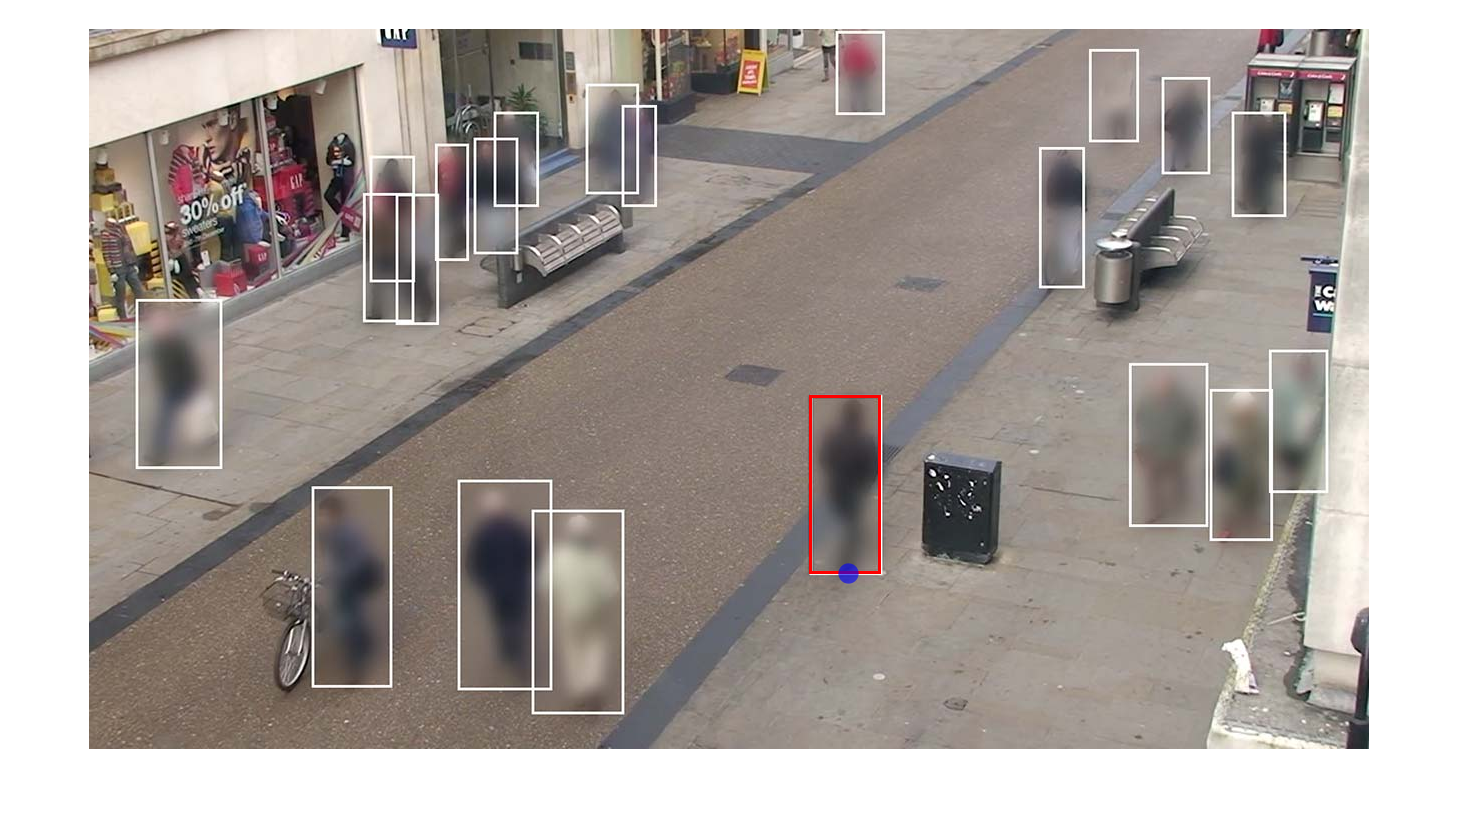

% image 정보 불러오기
img = imread("background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

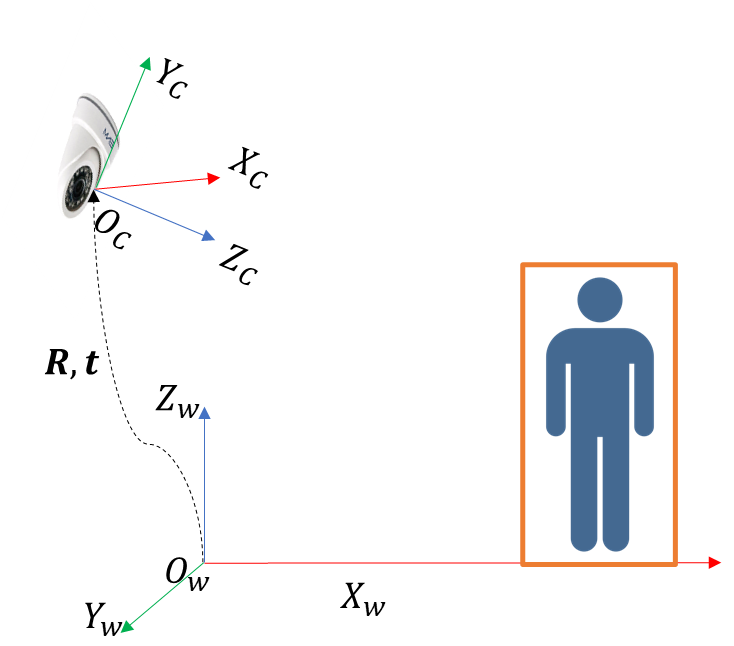

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = pi/2 - pi/6;  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도

% 위치
tx = 0;
ty = -5;
tz = 0.2

tz = 0.2000



% Camera Matrix?
Camera_Matrix = [fx 0 cx; 0 fy cy; 0 0 1]

Camera_Matrix =         1000           0         640
           0        1000         480
           0           0           1



% Rotation Matrix?
Rx = [1 0 0; 0 cos(theta_x) -sin(theta_x); 0 sin(theta_x) cos(theta_x)]

Rx =     1.0000         0         0
         0    0.5000   -0.8660
         0    0.8660    0.5000


Ry = [cos(theta_y) 0 sin(theta_y); 0 1 0; -sin(theta_y) 0 cos(theta_y)]

Ry =     0.0000         0   -1.0000
         0    1.0000         0
    1.0000         0    0.0000


Rz = [cos(theta_z) -sin(theta_z) 0; sin(theta_z) cos(theta_z) 0; 0 0 1]

Rz =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


Rotation_Matrix = Rz*Ry*Rx

Rotation_Matrix =     0.0000   -0.5000    0.8660
    0.0000   -0.8660   -0.5000
    1.0000    0.0000    0.0000



% Translation Matrix?
Translation_Matrix = [tx; ty; tz]

Translation_Matrix =          0
   -5.0000
    0.2000



% World Coordinate 좌표 값?
%World_Coordinate = [inv(Camera_Matrix)*[u; v; 1]; -Rotation_Matrix(1,:); -Rotation_Matrix(2,:)]*Translation_Matrix

다음 사용 중 오류가 발생함: vertcat
결합하려는 배열의 차원이 일치하지 않습니다.

Xw = 
